syms y(t)
[V ] = odeToVectorField(diff(y, 2) == (1 - y^2)*diff(y) - y)

$$V = \left(\begin{array}{c} Y_{2}\\ -\left({Y_{1}}^{2}-1\right)\,Y_{2}-Y_{1} \end{array}\right)$$


M = matlabFunction(V,'Vars',{'t', 'Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-(Y(1).^2-1.0).*Y(2)-Y(1)]


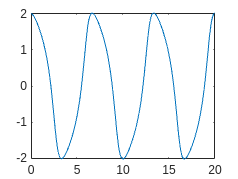


sol = ode45(M, [0 20], [2 0]);
fplot(@(x)deval(sol, x, 1), [0 20])